## **Abenezer Taye   Mini-Project 1**

clear all; close all; clc;

**For the assigned LTI system to your group: **

**A) Derive the differential equations to describe the model of the system.**

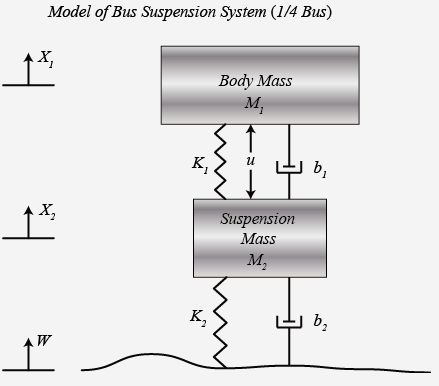

Considering each mass separately, we can write differential equations to describe the model of the system.

**For M1:**


$$\sum F=\mathrm{Ma}$$



$${-F}_{\mathrm{K1}} -F_{\mathrm{b1}} +U=M\ddot{X}$$



$$M_1 \ddot{x_1 } =-b_1 \left({\dot{x} }_1 -{\dot{x} }_2 \right)-k_1 \left(x_1 -x_2 \right)+u$$


**For M2: **


$$\sum F=\mathrm{Ma}$$



$$F_{\mathrm{K1}} +F_{\mathrm{b1}} +F_{\mathrm{K2}} +F_{\mathrm{b2}} -U=M\ddot{X}$$



$$M_2 \ddot{x_2 } =b_1 \left({\dot{x} }_1 -{\dot{x} }_2 \right)+k_1 \left(x_1 -x_2 \right)-b_2 \left(\dot{\dot{x_2 } -\dot{w} } \right)-k_2 \left(x_2 -w\right)-U$$


**b) Derive the state-space representation of the system. **

Using the above two differential equations as models of our system, we have two inputs **U** and **W**. And taking **X1** and **Y(X1-X2)** as our state variables: 


$$\ddot{x_1 } =\frac{-b_1 \left({\dot{x} }_1 -{\dot{x} }_2 \right)}{m_1 }-\frac{k_1 \left(x_1 -x_2 \right)}{m_2 }+\frac{u}{m_1 }$$



$$\ddot{x_2 } =\frac{b_1 \left({\dot{x} }_1 -{\dot{x} }_2 \right)}{m_2 }+\frac{k_1 \left(x_1 -x_2 \right)}{m_2 }-\frac{b_2 \left(\dot{\dot{x_2 } -\dot{w} } \right)}{m_2 }-\frac{k_2 \left(x_2 -w\right)}{m_2 }-\frac{u}{m_2 }$$



$$\ddot{x_1 } =\frac{-b_1 \left(\dot{y_1 } \right)}{m_1 }-\frac{k_1 \left(y_1 \right)}{m_1 }+\frac{u}{m_1 }$$
 


$$\ddot{x_2 } =\frac{b_1 \left(\dot{y_1 } \right)}{m_2 }+\frac{k_1 \left(y_1 \right)}{m_2 }-\frac{b_2 \left(\dot{\dot{x_2 } -\dot{w} } \right)}{m_2 }-\frac{k_2 \left(x_2 -w\right)}{m_2 }-\frac{u}{m_2 }$$



$$\ddot{y_1 } =-\left(\frac{b_1 }{m_1 }+\frac{b_1 }{m_2 }\right)\dot{\dot{y_1 } -\left(\frac{k_1 }{m_1 }+\frac{k_1 }{m_2 }\right)y_1 -\frac{b_2 \left(\dot{w} -\dot{x_2 } \right)}{m_2 }-\frac{k_2 \left(w-x_2 \right)}{m_2 }+\left(\frac{1}{m_1 }+\frac{1}{m_2 }\right)u}$$



$$\dot{y_1 } =-\left(\frac{b_1 }{m_1 }+\frac{b_1 }{m_2 }\right)y_1 -\frac{b_2 \left(w-x_2 \right)}{m_2 }+\int \left(\left(\frac{k_1 }{m_1 }+\frac{k_1 }{m_2 }\right)y_1 -\frac{k_2 \left(w-x_2 \right)}{m_2 }+\left(\frac{1}{m_1 }+\frac{1}{m_2 }\right)u\right)\mathrm{dt}$$



$$\dot{y_2 } =\left(\frac{k_1 }{m_1 }+\frac{k_1 }{m_2 }\right)y_1 -\frac{k_2 \left(w-x_2 \right)}{m_2 }+\left(\frac{1}{m_1 }+\frac{1}{m_2 }\right)u$$


 
$$y_1 =x_1 -x_2 ,x_2 =x_1 -y_1$$
 


$$\dot{y_2 } =\left(\frac{k_1 }{m_1 }+\frac{k_1 }{m_2 }\right)y_1 -\frac{k_2 \left(w-x_1 +y_1 \right)}{m_2 }+\left(\frac{1}{m_1 }+\frac{1}{m_2 }\right)u$$



$$\dot{y_1 } =-\left(\frac{b_1 }{m_1 }+\frac{b_1 }{m_2 }\right)y_1 -\frac{b_2 \left(w-x_1 +y_1 \right)}{m_2 }+y_2$$


Now we have a state space equation with state variables $x_1 ,\dot{x_1 ,} \;y_1 ,y_2$ with thier respective derivative.

Finally, the state space representation of the system will be:


$$\begin{array}{l}
\left\lbrack \begin{array}{c}
\dot{x_1 } \\
\ddot{x_1 } \\
\dot{y_1 } \\
\dot{y_2 } 
\end{array}\right\rbrack =\left\lbrack \begin{array}{cccc}
0 & 1 & 0 & 0\\
\frac{-b_1 b_2 }{m_1 m_2 } & 0 & \frac{b_1 }{m_1 }\left(\frac{b_1 }{m_1 }+\frac{b_1 }{m_2 }+\frac{b_2 }{m_2 }\right)-\frac{k_1 }{m_1 } & \frac{-b_1 }{m_1 }\\
\frac{b_2 }{m_2 } & 0 & -\left(\frac{b_1 }{m_1 }+\frac{b_1 }{m_2 }+\frac{b_2 }{m_2 }\right) & 1\\
\frac{k_2 }{m_2 } & 0 & -\left(\frac{k_1 }{m_1 }+\frac{k_1 }{m_2 }+\frac{k_2 }{m_2 }\right) & 0
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
x_1 \\
\dot{x_1 } \\
y_1 \\
y_2 
\end{array}\right\rbrack +\left\lbrack \begin{array}{cc}
0 & 0\\
\frac{1}{m_1 } & \frac{b_1 b_2 }{m_1 m_2 }\\
0 & \frac{-b_2 }{m_2 }\\
\left(\frac{1}{m_2 }+\frac{1}{m_2 }\right) & \frac{-k_2 }{m_2 }
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
u\\
w
\end{array}\right\rbrack \\
y=\left\lbrack \begin{array}{cccc}
0 & 0 & 1 & 0
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
x_1 \\
\dot{x_1 } \\
y_1 \\
y_2 
\end{array}\right\rbrack +\left\lbrack \begin{array}{cc}
0 & 0
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
u\\
w
\end{array}\right\rbrack 
\end{array}$$


c) From the state-space representation, **analytically (without using MATLAB)** find the system’s transfer function. 

**NOTE**: For this part, I have used Matlab's symbolic toolbox as the state-space representation is of 4th order and there is a lot of junk into it, which makes it very difficult to slove by hand.

To get the transfer function of our system from the state-space representation, we can use the formula: 


$$G\left(S\right)=C\left({\left(\mathrm{SI}-A\right)}^{-1} B+D\right)$$


syms s m1 m2 k1 k2 b1 b2 

A=[0 1 0 0; (-b1*b2/(m1*m2)) 0 (b1/m1*(b1/m1 + b1/m2 + b2/m2) - k1/m1) ...
    -b1/m1; b2/m2 0 -(b1/m1 + b1/m2 + b2/m2) 1; k2/m2 0 -(k1/m1 + k1/m2 +k2/m2) 0];

B=[0 0;1/m1 b1*b2/(m1*m2);0 -b2/m2; (1/m2 + 1/m2) -k2/m2];

C=[0 0 1 0];

D=[0 0];

In the above section, we just typed in our system. 

The inverse of a matrix (SI-A) can be computed as:


$${\left(\mathrm{SI}-A\right)}^{-1} =\frac{\mathrm{Adjoint}\left(\mathrm{SI}-A\right)}{\mathrm{determinant}\left(\mathrm{SI}-A\right)}$$


q=(s*eye(4)-A); 

delta=det(q);

Adj=adjoint(q);

q_inverse=(1/delta)*Adj; 

tfs=C*q_inverse*B;

Now from the above section we get two transfer functions, since we have two inputs. 


tf1i=tfs(1); %This is consideing U as input
tf2i=tfs(2); %This is considering W as input

%The first transfer function 

% k2 + b2 s   2 m1 s
% --------- + -------
%     #1         #1
% 
% where
% 
%                         3          3          3          2          2          2          4                              2
%    #1 == k1 k2 + b1 m1 s  + b1 m2 s  + b2 m1 s  + k1 m1 s  + k1 m2 s  + ...
% k2 m1 s  + m1 m2 s  + b1 k2 s + b2 k1 s + b1 b2 s


%The second transfer function 

% b1 b2 (k2 + b2 s)   k2 m1 s    b2 (m1 m2 s  + b1 b2 s + b1 k2)
% ----------------- - -------- - -------------------------------
%       m2 #1            #1                   m2 #1
% 
% where
% 
%                         3          3          3          2          2          2          4                              2
%    #1 == k1 k2 + b1 m1 s  + b1 m2 s  + b2 m1 s  + k1 m1 s  + k1 m2 s  ...
% + k2 m1 s  + m1 m2 s  + b1 k2 s + b2 k1 s + b1 b2 s


d) From the state-space representation, use **MATLAB** find the system’s transfer function. 

m1 = 2500;
m2 = 320;
k1 = 80000;
k2 = 500000;
b1 = 350;
b2 = 15020;

A=[0                 1   0                                              0
  -(b1*b2)/(m1*m2)   0   ((b1/m1)*((b1/m1)+(b1/m2)+(b2/m2)))-(k1/m1)   -(b1/m1)
   b2/m2             0  -((b1/m1)+(b1/m2)+(b2/m2))                      1
   k2/m2             0  -((k1/m1)+(k1/m2)+(k2/m2))                      0];

B=[0                 0
   1/m1              (b1*b2)/(m1*m2)
   0                -(b2/m2)
   (1/m1)+(1/m2)    -(k2/m2)];

C=[0 0 1 0];

D=[0 0];

[n1,d1]=ss2tf(A,B,C,D,1); %Transfer function with the first input 
[n2,d2]=ss2tf(A,B,C,D,2); %Transfer function with the second input 

tf1=tf(n1,d1);
tf2=tf(n2,d2);

%tf1 =
 
%       0.003525 s^2 + 0.01878 s + 0.625
%  ------------------------------------------
%  s^4 + 48.17 s^3 + 1851 s^2 + 1721 s + 5e04
 
%Continuous-time transfer function.



%tf2 =
 
%       0.003525 s^2 + 0.01878 s + 0.625
%  ------------------------------------------
%  s^4 + 48.17 s^3 + 1851 s^2 + 1721 s + 5e04
 
%Continuous-time transfer function.

**NOTE:** you can always remove the semicolon ';' to display the results

e) **Analytically** find the impulse response of the system and then use MATLAB to plot the impulse response of the system. 

The impulse response is given by the equaiton:


$$g\left(t\right)=Ce^{\mathrm{At}} B+D\delta \left(t\right)$$


As we can see from the above equation, in order to find the impulse response, we first need to find  $e^{\mathrm{At}}$. And to find $e^{\mathrm{At}}$, let's use the second method we learned in the class, which is given as:


$$e^{\mathrm{At}} =Qe^{\bar{A} t} Q^{-1}$$
 

where $\bar{A} =Q^{-1} \mathrm{AQ}$ and $Q$ is matrix composed of eigen vectors of A.


$$e^{\bar{A} t} =e^{\left(\bar{\mathrm{Ax}} t\right)}$$



$$e^{\mathrm{At}} =Qe^{\bar{A} t} Q^{-1}$$



$$g\left(t\right)=Ce^{\mathrm{At}} B+D\delta \left(t\right)$$


[Q,E]=eig(A); %where Q is a matrix that contains the eigen vectors and D is the set of eigen values

Qin = inv(Q);

A_bar = Qin*A*Q;
syms t

e_Abar =  exp(A_bar*t);
e_At=Q*e_Abar*Qin;

%% Impulse response
g_of_t = C*e_At*B;

Now, we got $g\left(t\right)$, which is actualy a 2x1 vector. Each element of the vector represents the impluse response of the system considering each of the two inputs. The next step is to plot the two responses.  

t=[0:0.01:50];

%"first" is the impulse response of the system considering U(t) as input
first = exp(t*(8.5093e-14 + 9.7420e-14i))*(1.7437e-06 - 6.9755e-06i) ...
    + exp(t*(8.9034e-14 - 1.0453e-13i))*(1.7437e-06 + 6.9755e-06i) + ...
    exp(t*(- 4.2613e-16 - 1.7871e-16i))*(1.7525e-04 - 2.9573e-05i) - ...
    exp(t*(- 1.7555e-15 - 6.2172e-15i))*(2.8259e-05 + 1.5267e-06i) - ...
    exp(t*(- 1.9706e-15 + 7.1054e-15i))*(2.8259e-05 - 1.5267e-06i) - ...
    exp(t*(2.9519e-14 + 1.3040e-13i))*(7.1061e-06 + 1.0958e-06i) - ...
    exp(t*(3.3460e-14 - 1.2329e-13i))*(7.1061e-06 - 1.0958e-06i) + ...
    exp(t*(- 3.7303e-14 - 2.8422e-14i))*(4.2030e-05 + 1.6503e-05i) + ...
    exp(t*(- 4.2633e-14 + 2.8422e-14i))*(4.2030e-05 - 1.6503e-05i) - ...
    exp(t*(- 23.9758 + 35.1869i))*(1.0746e-06 + 4.5141e-05i) - ...
    exp(t*(- 23.9758 - 35.1869i))*(1.0746e-06 - 4.5141e-05i) + ...
    exp(t*(3.1152e-16 + 5.4083e-16i))*(3.2371e-05 - 1.7475e-04i) + ...
    exp(t*(- 2.4300e-16 + 1.0107e-16i))*(1.7525e-04 + 2.9573e-05i) + ...
    exp(t*(3.3646e-16 - 6.2963e-16i))*(3.2371e-05 + 1.7475e-04i) + ...
    exp(t*(- 0.1098 - 5.2504i))*(1.0746e-06 + 2.8280e-05i) + ...
    exp(t*(- 0.1098 + 5.2504i))*(1.0746e-06 - 2.8280e-05i);
 
    
%"second" is the impulse response of the system considering U(t) as input
second = exp(t*(8.5093e-14 + 9.7420e-14i))*(0.1538 - 0.5647i) + ...
    exp(t*(8.9034e-14 - 1.0453e-13i))*(0.1538 + 0.5647i) - ...
    exp(t*(- 4.2613e-16 - 1.7871e-16i))*(7.4844 - 96.0736i) - ...
    exp(t*(- 1.7555e-15 - 6.2172e-15i))*(2.2971 + 0.1724i) - ...
    exp(t*(- 1.9706e-15 + 7.1054e-15i))*(2.2971 - 0.1724i) - ...
    exp(t*(2.9519e-14 + 1.3040e-13i))*(0.5802 + 0.0771i) - ...
    exp(t*(3.3460e-14 - 1.2329e-13i))*(0.5802 - 0.0771i) + ...
    exp(t*(- 3.7303e-14 - 2.8422e-14i))*(3.1549 - 24.2789i) + ...
    exp(t*(- 4.2633e-14 + 2.8422e-14i))*(3.1549 + 24.2789i) - ...
    exp(t*(- 23.9758 + 35.1869i))*(23.6044 - 6.5002i) - ...
    exp(t*(- 23.9758 - 35.1869i))*(23.6044 + 6.5002i) - ...
    exp(t*(3.1152e-16 + 5.4083e-16i))*(96.1810 - 5.9472i) -...
    exp(t*(- 2.4300e-16 + 1.0107e-16i))*(7.4844 + 96.0736i) - ...
    exp(t*(3.3646e-16 - 6.2963e-16i))*(96.1810 + 5.9472i) + ...
    exp(t*(- 0.1098 - 5.2504i))*(0.1356 + 2.2995i) + ...
    exp(t*(- 0.1098 + 5.2504i))*(0.1356 - 2.2995i);

As we can see from the above section, 'first' and 'second' are the two impulse responses of the systems, considering the two inputs. 

Now let's plot them and compare the two results (the one we solve analytically and the one we solve using matlab). 

f) Use **MATLAB** to find and plot the impulse repose of the system and compare the results with part (e). 

subplot(2,2,1)
[yt,x]=impulse(tf1);
plot(x,squeeze(yt), 'LineWidth',1.5 )
title('impulse response--first (Matlab)')

subplot(2,2,2)
plot(t,first,'LineWidth',1.5)
title('impulse response--first (Analytical)')

subplot(2,2,3)
[yy,x]=impulse(tf2)
plot(x,squeeze(yy), 'LineWidth',1.5 )
title('impulse response--second (Matlab)')

subplot(2,2,4)
plot(t,second,'LineWidth',1.5)
title('impulse response--second(Analytical)')


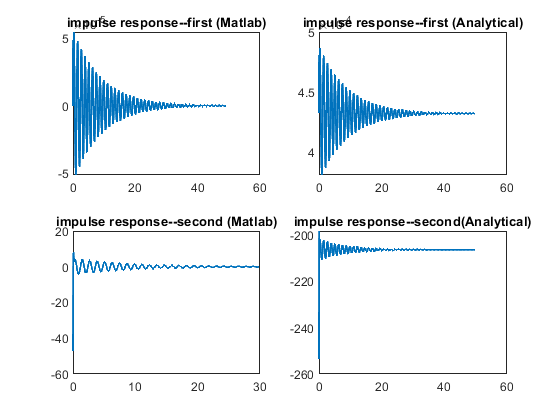

Unfortunately, as you can see from the above figures, even though the two methods provide similar results, there is also a discrepancy between the two curves. I believe that occurs due to the assumptions and approximations done by matlab while performing the symbolic martix invese and symbolic integration. 

G)** Analytically** find the step response of the system and then use **MATLAB** to plot the step response of the system. 

To find the step response analytically, we use the equation:


$$Y\left(t\right)=Ce^{\mathrm{At}} X\left(0\right)+C\int_0^t e^{A\left(t-\tau \right)} \mathrm{BU}\left(\tau \right)d\tau$$


But since our input is step signal, we can assign $U\left(\tau \right)$=1, if we assume the signal is a unit step signal. Also, if we assume the system is initially relaxed,  $Ce^{\mathrm{At}} X\left(0\right)=0$.

Hence, the above equation becomes,  


$$Y\left(t\right)=C\int_0^t e^{A\left(t-\tau \right)} \mathrm{Bd}\tau$$


$\bar{A} =Q^{-1} \mathrm{AQ}$ and $Q$ is matrix composed of eigen vectors of A

syms t T

e_Abar =  exp(A_bar*(t-T));


$$e^{\bar{A} t} =e^{\left(\left.\bar{A\left(\right.} t-\tau \right)\right)}$$


e_At_T=Q*e_Abar*Qin;


$$e^{\mathrm{At}} =Qe^{\bar{A\left(t-\tau \right)} } Q^{-1}$$


e_At_T=e_At_T*B;


$$e^{A\left(t-\tau \right)} =e^{A\left(t-\tau \right)} B$$


%% Step response
X_of_t=int(e_At_T,T,0,t);


$$X\left(t\right)=\int_0^t e^{A\left(t-\tau \right)} \mathrm{Bd}\tau$$



step_response=C*X_of_t;


$$Y\left(t\right)=C\int_0^t e^{A\left(t-\tau \right)} \mathrm{Bd}\tau$$


The above step input is a 2x1 vector. Each element of the vector represents the step response of the system considering each of the two inputs. The next step is to plot the two responses.

t=[0:0.01:50];

%"first_res" is the step response of the system considering U(t) as input
first_res = 1.3072e+12 - exp(t*(8.9034e-14 - 1.0453e-13i))*(3.0440e+07 - 4.2610e+07i) - ... 
    exp(t*(- 4.2613e-16 - 1.7871e-16i))*(3.2499e+11 - 2.0569e+11i) + ... 
    exp(t*(- 1.7555e-15 - 6.2172e-15i))*(1.4161e+09 - 4.1454e+09i) + ...
    exp(t*(- 1.9706e-15 + 7.1054e-15i))*(1.2238e+09 + 3.6377e+09i) - ...
    exp(t*(2.9519e-14 + 1.3040e-13i))*(1.9728e+07 - 5.0029e+07i) - ...
    exp(t*(3.3460e-14 - 1.2329e-13i))*(2.2846e+07 + 5.1436e+07i) - ...
    exp(t*(- 3.7303e-14 - 2.8422e-14i))*(9.2614e+08 - 2.6324e+08i) - ...
exp(t*(- 4.2633e-14 + 2.8422e-14i))*(8.6118e+08 + 1.8703e+08i) - ...
exp(t*(- 23.9758 + 35.1869i))*(8.6191e-07 - 6.1783e-07i) - ...
exp(t*(- 23.9758 - 35.1869i))*(8.6191e-07 + 6.1783e-07i) - ...
exp(t*(3.1152e-16 + 5.4083e-16i))*(2.1673e+11 + 1.8469e+11i) - ...
exp(t*(- 2.4300e-16 + 1.0107e-16i))*(5.7166e+11 + 3.5947e+11i) -...
exp(t*(3.3646e-16 - 6.2963e-16i))*(1.9452e+11 - 1.5536e+11i) - ...
exp(t*(- 0.1098 - 5.2504i))*(5.3881e-06 - 9.1953e-08i) - ...
exp(t*(- 0.1098 + 5.2504i))*(5.3881e-06 + 9.1953e-08i) - ...
exp(t*(8.5093e-14 + 9.7420e-14i))*(3.1747e+07 + 4.5629e+07i) + 1.8355e+11i;


%"second_res" is the step response of the system considering U(t) as input
second_res = 3.0353e+17 - exp(t*(8.9034e-14 - 1.0453e-13i))*(2.4046e+12 - 3.5194e+12i) ...
    - exp(t*(- 4.2613e-16 - 1.7871e-16i))*(6.5473e+16 + 1.9800e+17i) + ...
    exp(t*(- 1.7555e-15 - 6.2172e-15i))*(1.2230e+14 - 3.3494e+14i) + ...
    exp(t*(- 1.9706e-15 + 7.1054e-15i))*(1.0579e+14 + 2.9395e+14i) - ...
    exp(t*(2.9519e-14 + 1.3040e-13i))*(1.5202e+12 - 4.1049e+12i) - ...
    exp(t*(3.3460e-14 - 1.2329e-13i))*(1.7716e+12 + 4.2247e+12i) + ...
    exp(t*(- 3.7303e-14 - 2.8422e-14i))*(2.6024e+14 + 4.5257e+14i) + ...
    exp(t*(- 4.2633e-14 + 2.8422e-14i))*(2.1161e+14 - 4.2842e+14i) + ...
    exp(t*(- 23.9758 + 35.1869i))*(0.4383 + 0.3722i) + ...
    exp(t*(- 23.9758 - 35.1869i))*(0.4383 - 0.3722i) -...
    exp(t*(3.1152e-16 + 5.4083e-16i))*(6.8659e+16 - 1.3829e+17i) - ...
    exp(t*(- 2.4300e-16 + 1.0107e-16i))*(1.1394e+17 - 3.4797e+17i) - ...
    exp(t*(3.3646e-16 - 6.2963e-16i))*(5.6151e+16 + 1.2275e+17i) - ...
exp(t*(- 0.1098 - 5.2504i))*(0.4383 - 0.0167i) - ...
exp(t*(- 0.1098 + 5.2504i))*(0.4383 + 0.0167i) - ...
exp(t*(8.5093e-14 + 9.7420e-14i))*(2.5058e+12 + 3.7673e+12i) - 1.6550e+17i;



grid
subplot(2,2,1)
[yt,x]=step(tf1);
plot(x,squeeze(yt), 'LineWidth',1.5 )
title('Step response--first (Matlab)')

subplot(2,2,2)
plot(t,first_res,'LineWidth',1.5)
title('Step response--first (Analytical)')

subplot(2,2,3)
[yy,x]=step(tf2)
plot(x,squeeze(yy), 'LineWidth',1.5 )
title('Step response--second (Matlab)')

subplot(2,2,4)
plot(t,second_res,'LineWidth',1.5)
title('Step response--second(Analytical)')

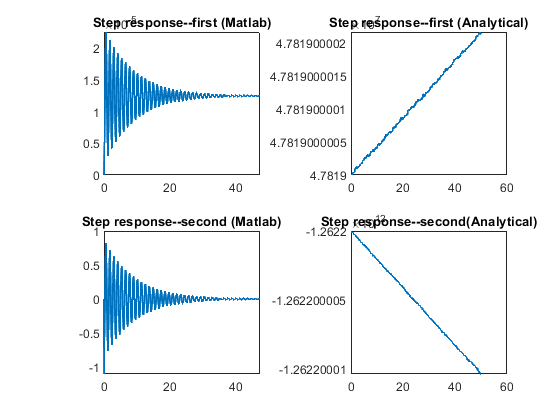

I believe MATLAB couldn't handle the symbolic integration well as our system is reasonably large and have complex . However, in order to verify the  above implementation, I have provided an additional computation by using a simpler system. 

%clear all; close all; clc;

A=[-1 2;0 1];
B=[1;1];
C=[0 1];
D=[0];
[n,d]=ss2tf(A,B,C,D);

tf=tf(n,d);
%step(tf1);

%%
[Q,E]=eig(A); %where Q is a matrix that contains the eigen vectors and E is the set of eigen values

Qin = inv(Q);

A_bar = Qin*A*Q;

syms t T

e_Abar =  expm(A_bar*(t-T));

e_At_T=Q*e_Abar*Qin;

e_At_T=e_At_T*B;

step_response=int(e_At_T,T,0,t);

step_response=C*step_response;

subplot(2,1,1)
[xy,x]=step(tf)
plot(x,squeeze(xy), 'LineWidth',1.5 )
title('Step Response (MATLAB)')
grid
subplot(2,1,2)
fplot(step_response(1),[0 60],'LineWidth',1.5);
title('Step Response (Analytical)')
grid


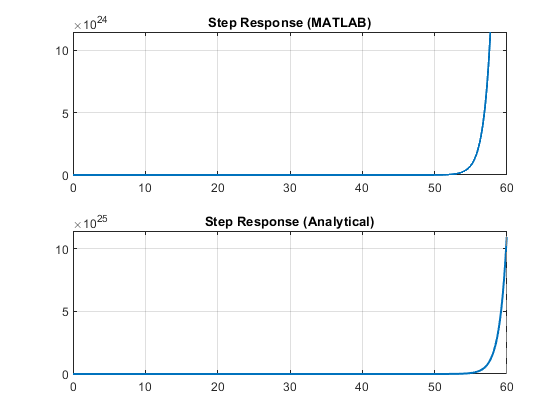

**Note:** As we can see from the above plots, the two methods ( matlab's "step" command and the exact algorithm we implemented in our problem) gives the same result. This verifies the implemented algorithm is a correct one and the fact that it didn't work for our problem is associated with the numerical computaiton performed by matlab, 

i)** Analytically** find the response of the system a step function for a nonzero initial condition and then use **MATLAB** to plot the response of the system. 

m1 = 2500;
m2 = 320;
k1 = 80000;
k2 = 500000;
b1 = 350;
b2 = 15020;

A=[0                 1   0                                              0
  -(b1*b2)/(m1*m2)   0   ((b1/m1)*((b1/m1)+(b1/m2)+(b2/m2)))-(k1/m1)   -(b1/m1)
   b2/m2             0  -((b1/m1)+(b1/m2)+(b2/m2))                      1
   k2/m2             0  -((k1/m1)+(k1/m2)+(k2/m2))                      0];

B=[0                 0
   1/m1              (b1*b2)/(m1*m2)
   0                -(b2/m2)
   (1/m1)+(1/m2)    -(k2/m2)];

C=[0 0 1 0];

D=[0 0];


[Q,E]=eig(A); %where Q is a matrix that contains the eigen vectors and D is the set of eigen values

Qin = inv(Q);

A_bar = Qin*A*Q;

syms t T

e_Abar =  exp(A_bar*(t-T));

e_At_T=Q*e_Abar*Qin;

e_At_T=e_At_T*B;

step_response=int(e_At_T,T,0,t);

step_response=C*step_response;

x0=[1;1;1;1];

e_Abar =  exp(A_bar*(t));

response=e_Abar*x0 + step_response;

%fplot(response(1),[0 60]);

Now let's plot the step responses

t=[0:0.01:50];

step1=1.3072e+12 - exp(t*(8.9034e-14 - 1.0453e-13i))*(3.0440e+07 - 4.2610e+07i) ...
    - exp(t*(- 4.2613e-16 - 1.7871e-16i))*(3.2499e+11 - 2.0569e+11i) +...
    exp(t*(- 1.7555e-15 - 6.2172e-15i))*(1.4161e+09 - 4.1454e+09i) + ...
exp(t*(- 1.9706e-15 + 7.1054e-15i))*(1.2238e+09 + 3.6377e+09i) - ...
exp(t*(2.9519e-14 + 1.3040e-13i))*(1.9728e+07 - 5.0029e+07i) - ...
exp(t*(3.3460e-14 - 1.2329e-13i))*(2.2846e+07 + 5.1436e+07i) - ...
exp(t*(- 3.7303e-14 - 2.8422e-14i))*(9.2614e+08 - 2.6324e+08i) - ...
exp(t*(- 4.2633e-14 + 2.8422e-14i))*(8.6118e+08 + 1.8703e+08i) + ...
exp(t*(- 23.9758 + 35.1869i))*(1.000 + 6.1783e-07i) - ...
exp(t*(- 23.9758 - 35.1869i))*(8.6191e-07 + 6.1783e-07i) - ...
exp(t*(3.1152e-16 + 5.4083e-16i))*(2.1673e+11 + 1.8469e+11i) - ...
exp(t*(- 2.4300e-16 + 1.0107e-16i))*(5.7166e+11 + 3.5947e+11i) -...
exp(t*(3.3646e-16 - 6.2963e-16i))*(1.9452e+11 - 1.5536e+11i) - ...
exp(t*(- 0.1098 - 5.2504i))*(5.3881e-06 - 9.1953e-08i) - ...
exp(t*(- 0.1098 + 5.2504i))*(5.3881e-06 + 9.1953e-08i) - ...
exp(t*(8.5093e-14 + 9.7420e-14i))*(3.1747e+07 + 4.5629e+07i) + 1.8355e+11i;

step2=1.3072e+12 - exp(t*(8.9034e-14 - 1.0453e-13i))*(3.0440e+07 - 4.2610e+07i)...
    - exp(t*(- 4.2613e-16 - 1.7871e-16i))*(3.2499e+11 - 2.0569e+11i) + ...
    exp(t*(- 1.7555e-15 - 6.2172e-15i))*(1.4161e+09 - 4.1454e+09i) + ...
    exp(t*(- 1.9706e-15 + 7.1054e-15i))*(1.2238e+09 + 3.6377e+09i) -...
    exp(t*(2.9519e-14 + 1.3040e-13i))*(1.9728e+07 - 5.0029e+07i) -...
    exp(t*(3.3460e-14 - 1.2329e-13i))*(2.2846e+07 + 5.1436e+07i) -...
    exp(t*(- 3.7303e-14 - 2.8422e-14i))*(9.2614e+08 - 2.6324e+08i) - ...
    exp(t*(- 4.2633e-14 + 2.8422e-14i))*(8.6118e+08 + 1.8703e+08i) - ...
    exp(t*(- 23.9758 + 35.1869i))*(8.6191e-07 - 6.1783e-07i) + ...
    exp(t*(- 23.9758 - 35.1869i))*(1.000 - 6.1783e-07i) - ...
    exp(t*(3.1152e-16 + 5.4083e-16i))*(2.1673e+11 + 1.8469e+11i) - ...
    exp(t*(- 2.4300e-16 + 1.0107e-16i))*(5.7166e+11 + 3.5947e+11i) - ...
    exp(t*(3.3646e-16 - 6.2963e-16i))*(1.9452e+11 - 1.5536e+11i) - ...
    exp(t*(- 0.1098 - 5.2504i))*(5.3881e-06 - 9.1953e-08i) - ...
    exp(t*(- 0.1098 + 5.2504i))*(5.3881e-06 + 9.1953e-08i) - ...
    exp(t*(8.5093e-14 + 9.7420e-14i))*(3.1747e+07 + 4.5629e+07i) + 1.8355e+11i;
 
grid
subplot(2,2,1)
[yt,x]=step(tf1);
plot(x,squeeze(yt), 'LineWidth',1.5 )
title('Step response--first (Matlab)')

subplot(2,2,2)
plot(t,step1,'LineWidth',1.5)
title('Step response--first (Analytical)')

subplot(2,2,3)
[yy,x]=step(tf2)
plot(x,squeeze(yy), 'LineWidth',1.5 )
title('Step response--second (Matlab)')

subplot(2,2,4)
plot(t,step2,'LineWidth',1.5)
title('Step response--second(Analytical)')

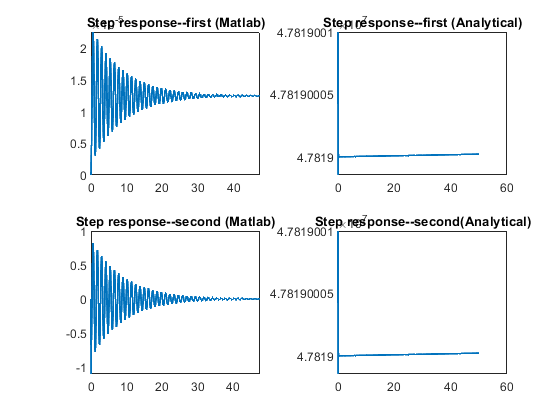

Just like we did for part **(h)**, we are not getting the correct result. But we can implement the exact same algorithm into a simpler system to see if the implementation is correct. 

%clear all; close all; clc;

A=[-1 2;0 1];
B=[1;1];
C=[0 1];
D=[0];

sys=ss(A,B,C,D);
x0=[1,1];

sys=ss(A,B,C,D);


Now, let's implement our algorithm and see if it will provide the same result with matlab's builtin command. 

[Q,E]=eig(A); %where Q is a matrix that contains the eigen vectors and D is the set of eigen values

Qin = inv(Q);

A_bar = Qin*A*Q;

syms t T

e_Abar =  expm(A_bar*(t-T));

e_At_T=Q*e_Abar*Qin;

e_At_T=e_At_T*B;

step_response=int(e_At_T,T,0,t);

step_response=C*step_response;

x0=[1;1];

e_Abar =  expm(A_bar*(t));

response=e_Abar*x0 + step_response;

subplot(2,1,1)
[in,t]=initial(sys,x0);
plot(t,squeeze(in), 'LineWidth',2 )
title('Response with inital condition(MATLAB)')
grid
subplot(2,1,2)
fplot(response(1),[0 60], 'LineWidth',2);
title('Response with inital condition(Analytical)')
grid

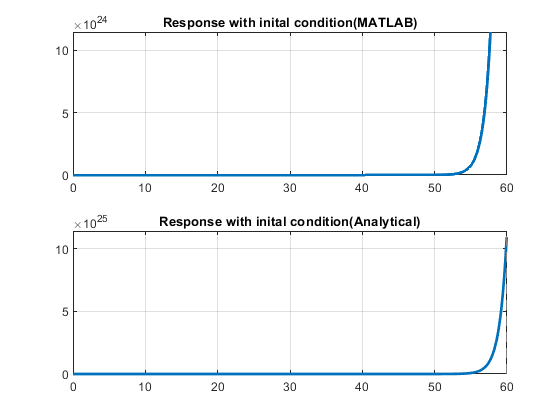

Therefore, our implementation is correct and the two methods (Analytical and Matlab) provide the same results. 

**k) Is the system BIBO stable?** 

Yes, it is BIBO stable because all of the eigen values of our A matrix **(-23.9758 +35.1869i, -23.9758 -35.1869i, -0.1098 + 5.2504i, -0.1098 - 5.2504i) **are less than zero. 

**l) Is the system stable in the sense of Lyapunov? **

Yes, it is stable in the sense of Lyapunov due to the same reason for part k.

**m) Is the system asymptomatically stable in the sense of Lyapunov?** 

Yes, it is asymptotically stable in the sense of Lyapunov due to the same reason for part k. 